## Name: Jhonatan TORRES

## Name: Valentin PORTILLO GALVAN 

# Random variables Generation: Acceptance-Rejection

The inversion method of the cumulative distribution function cannot always be used to generate a random variable. Indeed $F_Y$ is not always bijective (for example random variable that takes discrete values) or $F_Y$ is bijective but we don't have the analytic form of $F_Y^{-1}$. Therefore, another method has been developed: the Aceptance-Rejection method.

We would like to generate a density law $f$ using a generator of a density law $g$. To perform the Acceptance/Rejection method, we need to find a constant M such that $f\left(X\right)\le$$Mg(X)$ for all $X$.

The method is then the following:

    1. Generate $X\sim g$ and $$U\sim \mathcal{U}([0,1]).$$

    2. If $ $U\leq f(X)/Mg(X)$$, we accept $$Y=X$$ as a realisation of the density law f else if we repeat the operation.

## Questions:

    1. Show that we necessary have$ $M\geq 1.$$

                As we have: $f(X)\leq Mg(X)$ then, $\int_{-\infty }^{\infty } f\left(x\right)\mathit{dx}\le M\int_{-\infty }^{\infty } g\left(x\right)\mathit{dx}\Rightarrow 1\le M\Rightarrow M\ge 1$

    2. Can we generate a Cauchy law $$\varrho(0,1) f(x) = 1/(\pi(1+x^2))$$ from a normal law $ $\mathcal{N}(0,1)$$? Why?

                We have $h\left(x\right)=\frac{f\left(x\right)}{g\left(x\right)}\le M,$ it is possible to generate$f\left(X\right)$ from $g\left(X\right)$ if $h\left(x\right)$is bounded, so:

                $$f(x)=\varrho(0,1)  = \frac{1}{\pi(1+x^2)}$$     ,     $g(x) = \mathcal{N} (0,1)=\frac{1}{\sqrt{2\pi}}e^{-x^2/2}$

                
$$h(x)=\frac{f(x)}{g(x)}=\frac{\frac{1}{\pi(x^2+1)}}{\frac{1}{\sqrt{2\pi}}e^{-x^2/2}}=\sqrt{\frac{2}{\pi}}\frac{e^{x^2/2}}{(x^2+1)}$$


                To verify that $h\left(x\right)$is bounded we hope the function to be $0$ when $x\longrightarrow \infty$.

                
$$\lim_{x\rightarrow\infty}\frac{e^{-x^2/2}}{1+x^2}=\lim_{x\rightarrow\infty}\frac{-xe^{-x^2/2}}{2x}=\lim_{x\rightarrow\infty}\frac{-e^{-x^2/2}}{2}=\infty$$


                So no $M$satisfies $\frac{f\left(x\right)}{g\left(x\right)}\le M$.

    3. We want to show that the acceptance/rejection method gives effectively a random variable following the density law $f\ldotp$

        a. Justify the following equality:

                
$$P[Y\leq y]=\sum_{i=0}^{+\infty}P\left[ X\leq y,U\leq \frac{f(X)}{Mg(X)} \right]\left( P\left[ U\geq \frac{f(X)}{Mg(X)}\right] \right)^i$$


                We first take a binomial experiment and we have $Z$ as geometric R.V:

                
$$\begin{array}{l}
P\left(\mathrm{"acceptance"}\right)=\rho \\
P\left(\mathrm{"rejection"}\right)=1-\rho \\
P_Z \left(k\right)={\rho \left(1-\rho \right)}^{k-1} 
\end{array}$$


                then:

                
$$\sum_{k=1}^{\infty}P_Z(k)=\sum_{k=1}^{\infty}\rho (1-\rho)^{k-1}=1$$


                                
$$=\sum_{i=0}^{\infty} \rho(1-\rho)^i   \quad, \quad  i=k-1$$


                As we take from the initial statements:

                
$$\begin{array}{l}
P\left(\mathrm{"aceptance"}\right)=P\left\lbrack U\le \frac{f\left(x\right)}{\mathit{Mg}\left(x\right)}\right\rbrack \\
P\left(\mathrm{"rejection"}\right)=1-P\left\lbrack U\ge \frac{f\left(x\right)}{\mathit{Mg}\left(x\right)}\right\rbrack 
\end{array}$$


                We get:

                
$$\sum_{i=1}^{\infty}P\left[U\leq \frac{f(x)}{Mg(x)}\right]\left(P\left[ U\geq\frac{f(x)}{Mg(x)}\right] \right)^i=1$$


                And:

                
$$P[Y\leq y]=P\left[X\leq y|U\leq \frac{f(x)}{g(x)}\right]=\frac{P\left[X\leq y,U\leq \frac{f(x)}{Mg(x)}\right]}{P\left[U\leq \frac{f(x)}{Mg(x)}\right]}$$


                then:

                
$$P\left[U\leq \frac{f(x)}{Mg(x)}\right]=\frac{P\left[X\leq y,U\leq \frac{f(x)}{Mg(x)}\right]}{P[Y\leq y]}$$


                and finally:

                
$$\sum_{i=1}^{\infty}\frac{P\left[X\leq y,U\leq \frac{f(x)}{Mg(x)}\right]}{P[Y\leq y]}\left(P\left[ U\geq\frac{f(x)}{Mg(x)}\right] \right)^i=1$$


                Where we have that:

                
$$P[Y\leq y]=\sum_{i=1}^{\infty}P\left[X\leq y,U\leq \frac{f(x)}{Mg(x)}\right]\left(P\left[ U\geq\frac{f(x)}{Mg(x)}\right] \right)^i$$


        b. Show that:

                
$$P\left[ X\leq y,U\leq \frac{f(X)}{Mg(X)} \right]=\frac{1}{M}F_f(Y)$$
                        

            Where $F_Y \left(y\right)=\int_{-\infty }^y f\left(t\right)\mathrm{dt}$

                
$$P\left[ X\leq y,U\leq \frac{f(X)}{Mg(X)} \right]=\int_{-\infty}^y P\left[U\leq \frac{f(x)}{Mg(x)}| X=t\leq y\right] g(t)dt$$


                                                    
$$=\int_{-\infty}^y \frac{f(t)}{Mg(t)} g(t)dt=\frac{1}{M} \int_{-\infty}^y f(t) dt$$


        c. Deduce that $P\left\lbrack Y\le y\right\rbrack =F_f \left(y\right)\ldotp$

                By using the cumulative distribution formula, we can say:

                
$$P[Y\leq y]=F_Y(y)=\int_{-\infty}^y f(t)dt$$


    4. Show that the acceptance probability after one iteration of the algorithm is $1/M$ and that the mean of iterations needed to accept a value for $Y$ is equal to $M\ldotp$ What does that mean concerning the choice of the density law $f?$

                As: $P\left(U\leq\frac{f(Y)}{Mg(Y)}|Y=y\right)=\frac{f(y)}{Mg(y)}$

                Thus, as $Y$ has density $g\left(y\right)$:

                
$$\rho =\int_{-\infty}^\infty \frac{f(y)}{Mg(y)}g(y)dy=\frac{1}{M}\int_{-\infty}^\infty f(y)dy=\frac{1}{M}$$


                And taking the $E\left\lbrack N\right\rbrack$ of the geometric distribution, we have:

                
$$E[N]=\sum_{k=1}^{\infty}k\rho(1-\rho)^{k-1}=\rho\sum_{k=0}^\infty \sum_{l=k}^\infty(1-\rho)^{l}$$


                          
$$=\rho\sum_{k=0}^{\infty} \frac{1}{\rho}(1-\rho)^k=\sum_{k=0}^{\infty}(1-\rho)^k=\frac{1}{\rho}=M$$


    5. Application: Generation of a truncated Gaussian law. The goal of this question is to study and compare 2 different methods of generation of a Gaussian random variable left truncated to a threshold $s\ldotp$

##         a. First method

            We consider the following algorithm:

                i. Generate $X\sim \mathcal{N}(0,1)$

                ii. If $X>s$ then we accept $Y=X$ else if return to $i\ldotp$

            The previous algorithm allows to generate a random variable $Y$ having a density function $f(y)=\alpha{I}_{y>s } e^{-y^2/2} $

                i. Show that the normalisation constant $\alpha$ is equal to:

                    $\alpha=\sqrt{\frac{2}{\pi}}\frac{1}{erfc(s/\sqrt{2})}$ with $\mathrm{erfc}\left(x\right)=\frac{2}{\sqrt{\pi }}\int_x^{\infty } e^{-u^2 } \mathrm{du}\;$

                    As: $\int_{-\infty}^s f_Y(y)dy=0$

                    then: $\alpha \int_{s}^\infty e^{-(x/\sqrt2)^2}dx =1$

                    So: $\alpha = \frac{1}{\int_{s}^\infty e^{-x^2/2}dx}$

                    if: $u=\frac{x}{\sqrt{2}}$ , $\mathit{du}=\frac{1}{\sqrt{2}}\mathit{dx}$, then: ${\int_{s}^\infty e^{-x^2/2}dx=\frac{1}{\sqrt2} \int_{s/\sqrt{2}}^\infty e^{-u^2}du \rightarrow erfc(s/\sqrt2) =\frac{2}{\sqrt\pi}\int_{s/\sqrt{2}}^\infty e^{-u^2}du $

                ii. We set $M_1^{-1} =\frac{1}{2}\mathrm{erfc}\left(\frac{s}{\sqrt{2}}\right)$

                    Show that the acceptance probability after one iteration is equal to $M_1^{-1}$ and that the mean of needed iterations to accept a value for $Y$ is equal to $M_1 \ldotp$

                    
$$M=\frac{f(x)}{g(x)}=\frac{\sqrt\frac{2}{\pi}\frac{e^{-x^2/2}}{erfc(s/\sqrt2)}}{\frac{1}{\sqrt{2\pi}}e^{-x^2/2}}=\frac{2}{erfc(s/\sqrt2)}=M_1^{-1
}$$


                    And as we already proved in question 4, the mean is ${\frac{1}{M}=M}^{-1} =M_1 =\frac{2}{\mathrm{erfc}\left(\frac{s}{\sqrt{2}}\right)}\ldotp$

##         b. Acceptance-Rejection method

            We implement the acceptance/rejection method with the exponential law $g(x)={I}_{x\geq s} \lambda e^{-\lambda(x-s)}$ as instrumental law.

                i. Generate an exponential random variale of law $g(x)={I}_{x\geq s} \lambda e^{-\lambda(x-s)}$. Let us define $$U\sim \mathcal{U}([0,1])$$ and $X=s-\frac{1}{\lambda }\mathrm{ln}\left(U\right)\ldotp$Show that $X$ has $g\left(x\right)$ as density function.

                From Previous Lab, as we know that if an F is a growing and bijective function we can state that Y = G(U) has a cumulative distribution function G = $F_Y^{-1}$.

                Let X = $F^{-1}$(U) = S - $\frac{1}{\lambda }\mathrm{ln}\left(U\right)$

                if we calculate the CDF of g(x), we have:

                
$$G\left(x\right)=\int_s^x \lambda e^{-\lambda \left(x-s\right)} =1-e^{-\lambda \left(x-s\right)}$$


                Let $Y=G^{-1} \left(U\right)$ being $U\text{ }=\text{ }1-e^{-\lambda \left(x-s\right)}$, so $e^{-\lambda \left(x-s\right)} =1-U$ and $\mathrm{ln}\left(1-U\right)=-\lambda \text{ }\left(y-s\right)$

                from this we got $y=s-\frac{1}{\lambda }\mathrm{ln}\left(1-U\right)$

                so, the RV $Y=S-\frac{1}{\lambda }\mathrm{ln}\left(1-U\right)$ has g(x) as density function and since U follows a uniform law, 1 - U follows the same uniform law.

                Let $\mathrm{U1}=1\text{ }-\mathrm{U2}$

                So we got $Y=S-\frac{1}{\lambda }\mathrm{ln}\left(1-\mathrm{U1}\right)=S-\frac{1}{\lambda }\mathrm{ln}\left(\mathrm{U2}\right)=X$

                And then, X has G(x) as distribution function and g(x) as density function.

                ii. Show that $\frac{f\left(x\right)}{g\left(x\right)}$ is over-calculed by $M_2 =\frac{\alpha }{\lambda }e^{\frac{\lambda^2 }{2}-\lambda s} \ldotp$

                Let $h\left(x\right)=\frac{f\left(x\right)}{g\left(x\right)}\text{ }$, in order to get hightlights about this function, we differentiate:

                
$$\mathrm{h'}=\frac{\mathrm{f'}}{\mathrm{g'}}=\frac{\mathrm{f'g}-\mathrm{g'f}}{g^2 }=\frac{-\alpha xe^{-\frac{x^2 }{2}} \ast \lambda e^{-\lambda \left(x-s\right)} -\left(-\lambda^2 e^{-\lambda \left(x-s\right)} \ast \alpha e^{-\frac{x^2 }{2}} \right)}{\lambda^2 e^{-2\lambda \left(x-s\right)} }=\frac{\left(\alpha \lambda e^{-\frac{x^2 }{2}} \ast \lambda e^{-\lambda \left(x-s\right)} \right)\left(\lambda -x\right)}{\lambda^2 e^{-2\lambda \left(x-s\right)} }$$


                from the differentiation, we are interested in the $\left(\lambda -x\right)$element since all the otheres will be positive. Then we deduce that for $x=\lambda$we got a maximum since when $x>\lambda ,\mathrm{h'}\left(x\right)<0\text{ }\mathrm{and}\text{ }\mathrm{for}\text{ }x<\lambda ,\mathrm{h'}\left(x\right)>0$.

                
$$h\left(\mathrm{max}\right)=h\left(\lambda \right)=\frac{\alpha }{\lambda }\ast \frac{e^{-\frac{\lambda^2 }{2}} }{e^{-\lambda \left(\lambda -s\right)} }=\frac{\alpha }{\lambda }\ast e^{\lambda \left(\frac{\lambda }{2}-2\right)}$$


                So, h(x) is over valued by $M_2 =h\left(\mathrm{max}\right)=h\left(\lambda \right)$ 

                iii. Deduce that the value of $\lambda$ that minimizes the number of iterations in the acceptance-rejection algorithm is equal to:

                        $\lambda=\frac{s+\sqrt{s^2+4}}{2}$ and find the mean of iterations needed to accep one value of $Y$for that choice of $\lambda \ldotp$

                In order to get hightlights of $M_2$ we are going to differentiate this and study its behavior.

                ${\mathrm{M'}}_2 \left(\lambda \right)=\frac{\alpha \left(\lambda^2 -s\lambda -1\right)e^{\frac{\lambda^2 }{2}-s\lambda } }{\lambda^2 }$, from this, we study just $\left(\lambda^2 -s\lambda -1\right)$since the other values will be possitive all the time for $\lambda$.

                $\lambda_{1,2} =\frac{s+-\sqrt{s^2 +4}}{2}$ are the roots of $\left(\lambda^2 -s\lambda -1\right)$, since the coefficient of the squared element is positive, the quadratic function it represents, that first it decreases and then increases, and it passes through the zero value on those roots.

                So, for the $M_2$, we deduce that first it will go up, after it will reach the minimum root as its maximum $\left(\frac{s-\sqrt{s^2 +4}}{2}\right)$, it will descend until $\frac{s+\sqrt{s^2 +4}}{2}$ where it reaches it local minimum and then it goes up again.

                So, in the point $M_2 \left(\lambda =\frac{s+\sqrt{s^2 +4}}{2}\right)=\frac{2\alpha }{s+\sqrt{s^2 +4}}e^{\frac{{\left(\frac{s+\sqrt{s^2 +4}}{2}\right)}^2 }{2}-s\left(\frac{s+\sqrt{s^2 +4}}{2}\right)} =\frac{2\alpha e^1 }{s+\sqrt{s^2 +4}}$ is value of $\lambda$that minimizes the number of iterations in the acceptance rejection algorithm.

##         c. Comparison of the two methods

                i. Compare $M_1$and $M_2 \ldotp$ Show that for large value of $s$ the second method is better than the first one in terms of the mean of needed iterations. Estimate numerically the value of $s$ for which the acceptance-rejection method is better than the first one.

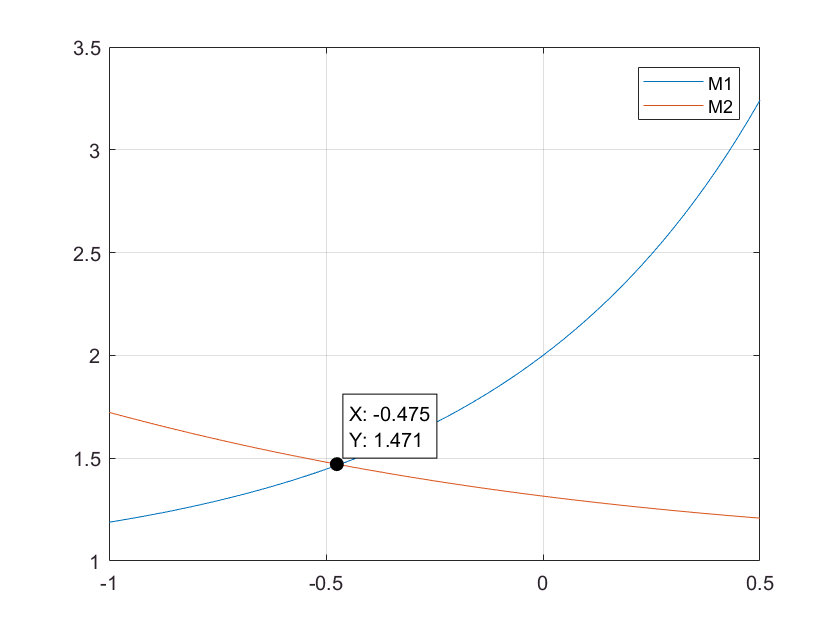

clear; clc; close all;

T = 10000; % samples
s = -1:0.025:0.5; %proposed values of S
U = rand(T,1);
alpha = sqrt(2/pi) * (1 ./ (erfc(s./sqrt(2))));

M1 = 2./erfc (s / sqrt(2));

lambda = (s + sqrt(s .* s + 4)) / 2;
M2 = (alpha ./ lambda) .* exp((lambda .* lambda/2) - lambda .* s);

plot(s, M1); hold on; plot(s, M2); grid on; legend("M1","M2")

So, from this plot, we can observe that the point where both, M1 and M2 intersect is around $s=-0\ldotp 475$. Then we can deduce that before this point M1 will have a better acceptance ratio and after this point, to choose M2, will be a better option.

                ii. Choose a value of $s$ for which the acceptance rate is high for the two methods. Generate with each method $T=10000$ samples. Verify for the two methods that the mean of needed iteration is in concordance with the theoretical value.

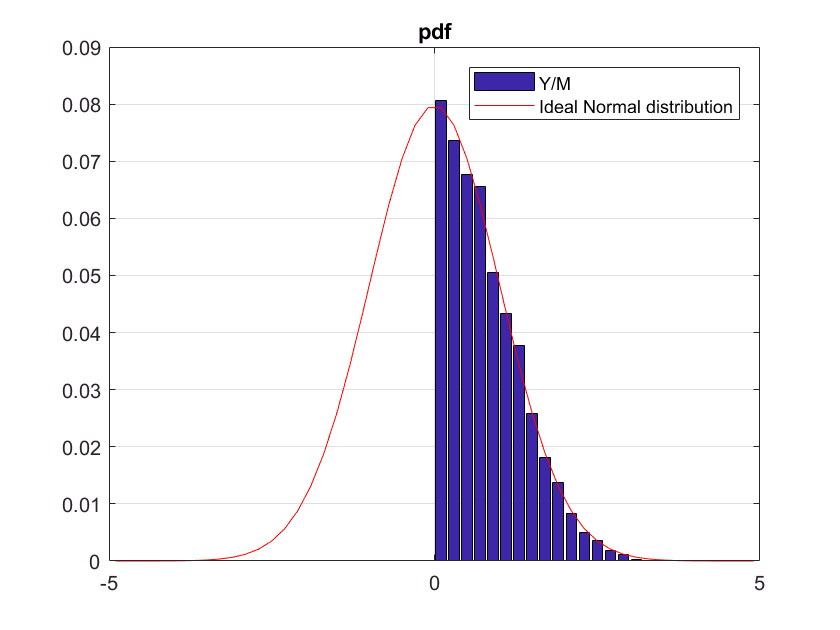

clear; clc; close all;

s = 0;

n = 10000; % Samples
x = randn(n,1); % N[0,1]
y = x>s; % Condition
P_r = sum(~y)/n; % P["rejection"]
y = x.*y; % Y distribution

nd = 50; % Number of bars in the graph
p = linspace(-5,5,nd+1); % Auxiliar points to plot
pdf = histcounts(y,p)/n; % Get histogram
pdf(nd/2+1) = pdf(nd/2+1)-P_r; % Take out the unnecesary counts in 0
p = (p(1:end-1) + p(2:end))/2; % Get central points
bar(p,pdf); title("pdf"); grid on;

z = (1/sqrt(2*pi))*exp(-((p).^2/(2)))*(p(2)-p(1));
hold on; plot(p,z,'r'); legend("Y/M","Ideal Normal distribution")

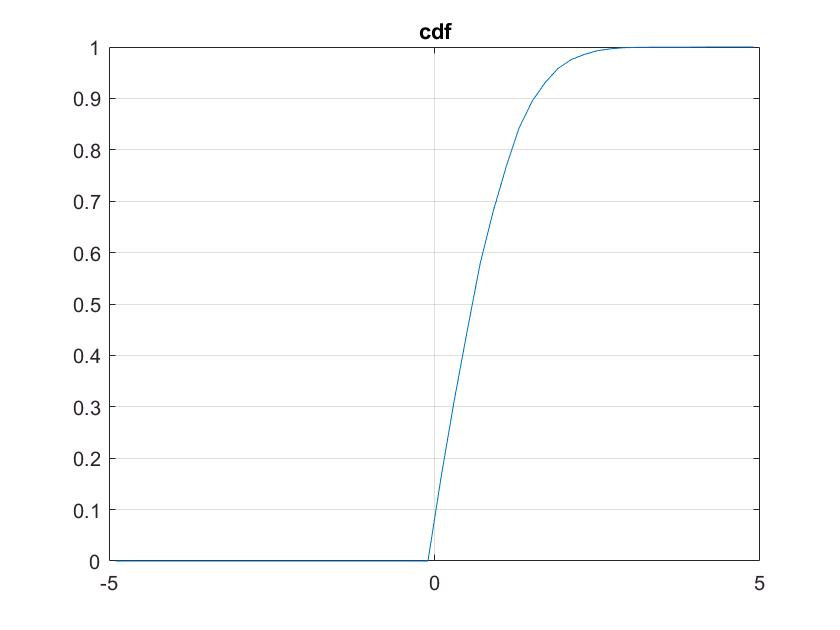

cdf = cumsum(pdf);
alpha = 1/cdf(end); % Catch value of M
cdf = cdf*alpha;  % CDF of the final distribution
figure; plot(p,cdf); title("cdf"); grid on;


s

s = 0

alpha

alpha = 2.0105

P_a = 1 - P_r

P_a = 0.4974

From this results we learned that, for different values of s, the cdf just moves along the x axis (here the p axis) with different values of s having a better fit when s is equal to 0 thinking of any normal distribution shape since it can take into account more important values than if we make s tend to infinity for example.

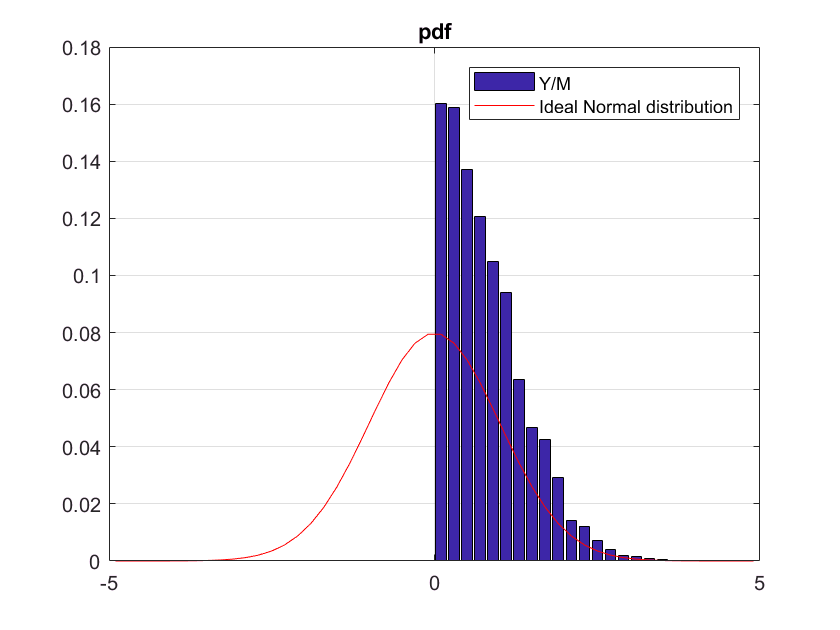

clear; clc; close all;

n = 10000;

s = 0;
lambda = (s+sqrt(s^2+4))/2;

x = s-log(rand(n,1))/lambda;
u = rand(n,1);
y = zeros(n,1);
c = (lambda*sqrt(2*pi)); 
P_r = 0;

for i=1:n
    if (u(i)<=(exp(-x(i)^2/2)/(c*exp(-lambda*x(i)))))
        y(i) = x(i);
    else
        P_r = P_r+1;
    end
end
P_r = P_r/n;

nd = 50; % Number of bars in the graph
p = linspace(-5,5,nd+1); % Auxiliar points to plot
pdf = histcounts(y,p)/n; % Get histogram
pdf(nd/2+1) = pdf(nd/2+1)-P_r; % Take out the unnecesary counts in 0

cdf = cumsum(pdf);
alpha = 1/cdf(end); % Catch value of M
pdf = pdf*alpha;
cdf = cdf*alpha;  % CDF of the final distribution

p = (p(1:end-1) + p(2:end))/2; % Get central points
bar(p,pdf); title("pdf"); grid on;
z = (1/sqrt(2*pi))*exp(-((p).^2/(2)))*(p(2)-p(1));
hold on; plot(p,z,'r'); legend("Y/M","Ideal Normal distribution")

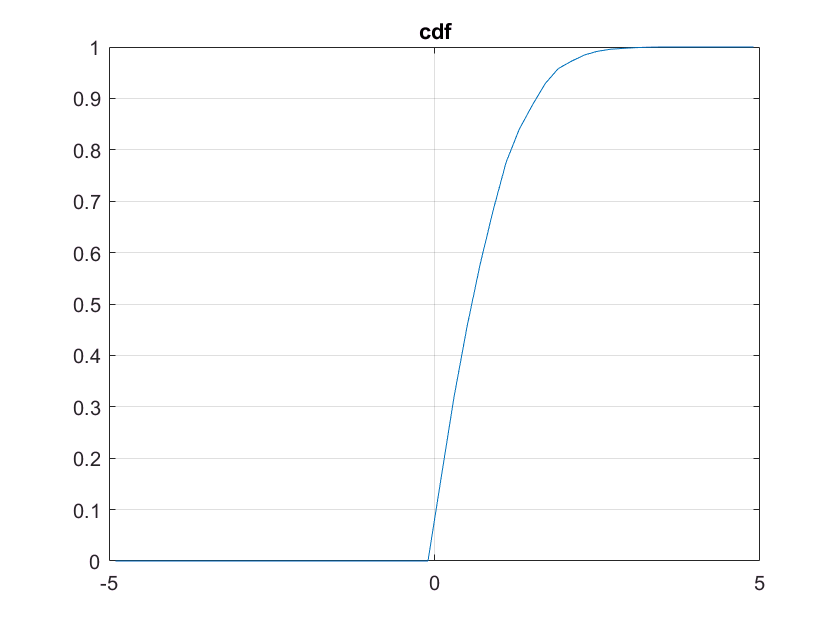

figure; plot(p,cdf); title("cdf"); grid on;

s

s = 0

alpha

alpha = 2.0028

P_a = 1 - P_r

P_a = 0.4994

In the previous plot we apply the accept and rejection algorithm by simulating random values with an uniform distribution and by counting those that are inferior to the exponential law (depending on s) to which it is compared, and suming this occurrences in order to get the acceptance rejection ratio.

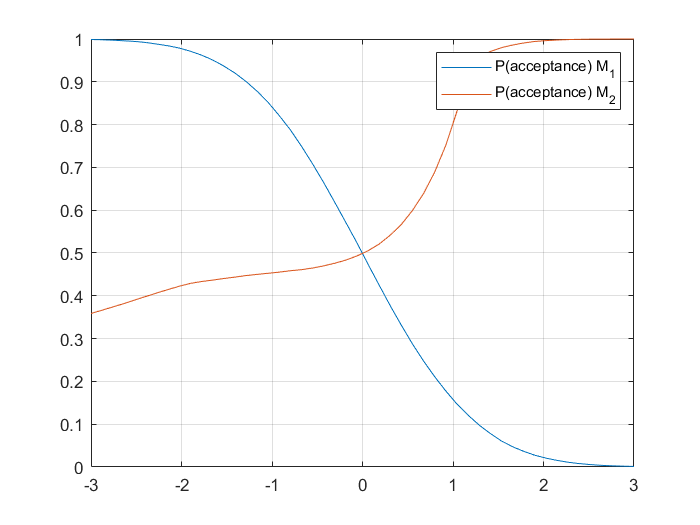

clear; clc; close all;

s = linspace(-3,3,50);
P_a_1 = zeros(size(s));
P_a_2 = zeros(size(s));
n = 100000;

x = randn(n,1);
for i=1:length(s)
    y = x>s(i);
    P_a_1(i) = sum(y)/n;
end

u1 = rand(n,1);
u2 = rand(n,1);
for i=1:length(s)
    lambda = (s(i)+sqrt(s(i)^2+4))/2;
    x = s(i)-log(u1)/lambda;
    y = zeros(n,1);
    c = (lambda*sqrt(2*pi));
    for j=1:n
        if (u2(j)<=(exp(-x(j)^2/2)/(c*exp(-lambda*x(j)))))
            P_a_2(i) = P_a_2(i)+1;
        end
    end
end
P_a_2 = P_a_2/n;
plot(s,P_a_1,s,P_a_2), grid on; legend("P[a] First method","P[a] Acceptance-rejection")

We find an intersection in s = 0, showing that the values for which s < 0, the probabilities of acceptance using the first method are better that for the second, eventhough the second is still able to have non neglectable values for a smaller s contrary to the first method for s > 0 where s excels notably tracing an exponential improvement. So from the two is for sure better to use the first method for values less than 0, although if we are constrained to use just one, the second method behaves much better in both cases and notably for s > 0.